# Using Functions and Projectors

## Introduction

In these tutorial files, you will learn how to use the various modules of Swan in order to generate your own FEM and Topology Optimization simulations. In each tutorial, a single building block will be analyzed, with some examples to make it easier. If you have any questions, feel free to create a new issue in the GitHub repository.

In this tutorial, we will learn how to use Functions and Projectors in Swan.

## Functions and projectors

Swan's `Functions` represent mathematical functions. First of all, their domain needs to be defined using a Mesh:

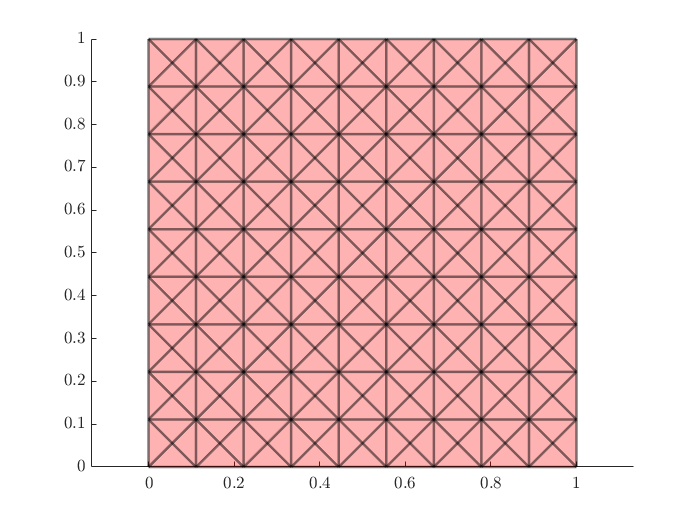

close all;

x1 = linspace(0,1,10);
x2 = linspace(0,1,10);
[xv,yv] = meshgrid(x1,x2);
[F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');
sBg.coord  = V(:,1:2);
sBg.connec = F;
mesh = Mesh(sBg);
figure
mesh.plot()

Having created a mesh, we can now dive deeper into the various functions that Swan includes. We can start with AnalyticalFunction, which uses a function handle to determine its value:

sAF.fHandle = @(x) x(1,:,:); % f(x) = x
sAF.ndimf   = 1; % number of dimensions
sAF.mesh    = mesh;
xFun = AnalyticalFunction(sAF);

We can project this function onto various different spaces, including P0, P1, and P1 Discontinuous:

p0fun = xFun.project('P0');
p1fun = xFun.project('P1');

Quadrature not implemented for triangle elements


Index in position 1 exceeds array bounds.

Error in Triangle_Linear/computeShapes (line 32)
            s = posgp(1,:,:);

Error in Triangle_Linear/computeShapeDeriv (line 12)
            obj.computeShapes(xGauss);

Error in 

These functions have additional useful methods:

- *evaluate(xG)*: returns the values of the functions at the given Gauss points

- *plot()*: plot the function in Matlab

- *print(filename, software)*: print the function to visualize it in GiD or Paraview

## Miss anything?

Feel free to create a new Issue in Swan's GitHub repository with any questions or doubts you may have. We will get back to you as soon as possible!